# Linear Control Design 2

# Solution to group work in module 5

clear
close all
clc

## Question 1 and 2 - Define new system

The state vector is ${\left\lbrack \begin{array}{c}
i & x_1  & v_1  & x_2  & v_2  & x_3  & v_3 
\end{array}\right\rbrack }^T$

m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

l = 24e-3; % mm, small
r = 14e-3 / 2;
A = pi*r^2;
R = 148.2;
L = 800e-3; % [H]
iMax = 0.14; % measured at 24v

gam = 0.5;          % bias ratio - normally chosen between 0.2-0.5
ib = iMax*gam;      % Bias current
mu = 4*pi*1e-7;     % Permeability of free space (vacuum)

b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1 = 0.145;         % [m] length of beam 1
L2 = 0.134;         % [m] length of beam 2
L3 = 0.229;         % [m] length of beam 3

% Force constants obtained from the linearisation
% 5 mm gap
s0 = 3e-3;
N = sqrt(L*2*abs(s0) / (mu*A));
Ki = mu*N^2*ib*A/s0^2;
Ks = -mu*N^2*ib^2*A/s0^3;

% Equivalent stiffness of beams
% with boundary condition clamped-clamped
k1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
k2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
k3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3

System matrices. 

A1 is the old system matrix from module 4 and earlier with actuators on mass 1.

A2 is the new system matrix with the actuators on mass 2 (middle mass)

% Old system matrix
A1 = [-R/L, 0, Ki/L, 0, 0, 0, 0;
     0, 0, 1, 0, 0, 0, 0;
     -Ki/m1, -(k1+k2+Ks)/m1, 0, k2/m1, 0, 0, 0;
     0, 0, 0, 0, 1, 0, 0;
     0, k2/m2, 0, -(k2+k3)/m2, 0, k3/m2, 0;
     0, 0, 0, 0, 0, 0, 1;
     0, 0, 0, k3/m3, 0, -k3/m3,0]

A1 =       -185.25            0       46.667            0            0            0            0
            0            0            1            0            0            0            0
      -52.434      -9220.7            0       5837.2            0            0            0
            0            0            0            0            1            0            0
            0       9710.5            0       -11656            0       1945.6            0
            0            0            0            0            0            0            1
            0            0            0       1945.6            0      -1945.6            0



% New system matrix
A2 = [-R/L 0 0 0 +Ki/L 0 0;
     0 0 1 0 0 0 0;
     0 -(k1+k2)/m1 0 k2/m1 0 0 0;
     0 0 0 0 1 0 0;
     -Ki/m2 k2/m2 0 -(k2+k3+Ks)/m2 0 k3/m2 0;
     0 0 0 0 0 0 1;
     0 0 0 k3/m3 0 -k3/m3 0]

A2 =       -185.25            0            0            0       46.667            0            0
            0            0            1            0            0            0            0
            0       -10444            0       5837.2            0            0            0
            0            0            0            0            1            0            0
      -87.227       9710.5            0      -9620.8            0       1945.6            0
            0            0            0            0            0            0            1
            0            0            0       1945.6            0      -1945.6            0



B = [1/L 0 0 0 0 0 0]'

B =          1.25
            0
            0
            0
            0
            0
            0


disp('Because the input V is injected to the circuit, the B matrix is not changing')

Because the input V is injected to the circuit, the B matrix is not changing


C = [0 1 0 0 0 0 0] % Measure x1

C =      0     1     0     0     0     0     0


D = 0;

## Question 3 and 4 - Find $\Lambda$ and $\mathbf{M}$ and compare.

% Calculate M and eigenvalues, 
[Mo,lbd_old,Vo] = eig(A1); % For the old system
lbd_old = diag(lbd_old)

lbd_old =       -174.09 +          0i
       -1.898 +     136.17i
       -1.898 -     136.17i
      -2.7637 +     61.332i
      -2.7637 -     61.332i
     -0.91794 +      31.18i
     -0.91794 -      31.18i



[M,lbd,V] = eig(A2);
lbd = diag(lbd)

lbd =       -166.26 +          0i
      -3.8492 +     135.42i
      -3.8492 -     135.42i
      -2.6698 +     27.229i
      -2.6698 -     27.229i
      -2.9736 +     60.796i
      -2.9736 -     60.796i


We note that the real part of all eigenvalues are still negative, so the system is locally stable around our linearisation point $\left(i_0 ,s_0 \right)$. Try also with $s_0 =1\mathrm{mm}$ and see what happens with the eigenvalues.

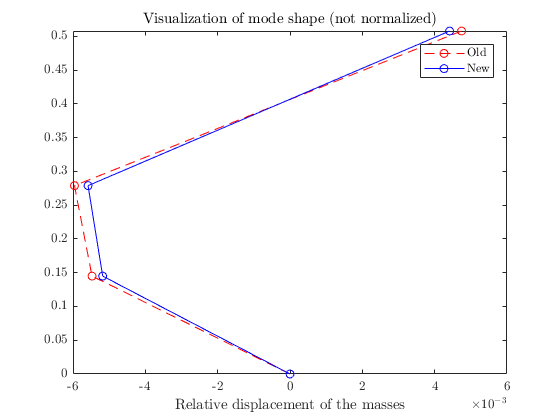

% Visualization
% Here the displacements (x1,x2,x3) of a mode shape is visualized.
theta = pi/6; % Some angle to rotate the complex values. Just to make the plot clearer.
% If you want to animate: vary theta from 0 to 2pi

% Setting an index for 
ind1 = 4; % Which mode (column in Mo) to use
ind2 = 6; % Which mode (column in M) to use 

v1 = Mo([2,4,6],ind1).*(cos(theta)+1i*sin(theta));
v2 = M([2,4,6],ind2).*(cos(theta)+1i*sin(theta));
v1 = [0;v1]; % Insert 0 as first element.
v2 = [0;v2];
y = [0, L1, L1+L2, L1+L2+L3]; % Just as
figure()
plot(real(v2),y,'--or',real(v1),y,'-ob')
title('Visualization of mode shape (not normalized)')
xlabel('Relative displacement of the masses')
legend('Old', 'New');
ylim([0,L1+L2+L3]);

disp('Corresponding eigenvalues')

Corresponding eigenvalues


disp('Old')

Old


disp(lbd_old(ind1))

      -2.7637 +     61.332i



disp('New')

New


disp(lbd(ind2))

      -2.9736 +     60.796i



The eigenvalues have all changed. The mode 

The mode with (+x1,+x2, -x3) (shown) 

% Calulate P for transformation into modal coordinates
% z = Px or x = P^(-1).z with P = M^(-1)
Po = inv(Mo);
P = inv(M)

P =       -1.1639 + 5.1137e-18i      -10.738 + 2.1798e-15i     0.064584 - 4.2134e-17i       12.196 +          0i      0.25332 +          0i      -2.7694 - 1.1614e-15i     0.016657 - 6.9389e-17i
     -0.11541 +   0.063923i       1.8316 -     56.646i     -0.41835 -  0.0016338i      -2.1814 +      42.78i      0.33926 +   0.046239i       0.5507 -     5.4716i    -0.040489 -  0.0029158i
     -0.11541 -   0.063923i       1.8316 +     56.646i     -0.41835 +  0.0016338i      -2.1814 -      42.78i      0.33926 -   0.046239i       0.5507 +     5.4716i    -0.040489 +  0.0029158i
     -0.11951 +   0.010955i       -1.171 +      6.849i      0.25332 +    0.01817i       4.5087 +     6.3549i      0.25357 +   0.014376i      -2.9966 +     10.669i      0.39877 +   0.070954i
     -0.11951 -   0.010955i       -1.171 -      6.849i      0.25332 -    0.01817i       4.5087 -     6.3549i      0.25357 -   0.014376i      -2.9966 -     10.669i      0.39877 -   0.070954i
      0.11211 -   0.044878i       1.0102 -    


% Calculate Bt
Bto = Po*B

Bto =        1.3421 - 1.1137e-17i
     0.092335 -   0.066376i
     0.092335 +   0.066376i
      0.13049 -    0.05101i
      0.13049 +    0.05101i
    -0.082769 +   0.016208i
    -0.082769 -   0.016208i


Bt = P*B

Bt =       -1.4549 + 6.3921e-18i
     -0.14427 +   0.079904i
     -0.14427 -   0.079904i
     -0.14939 +   0.013694i
     -0.14939 -   0.013694i
      0.14014 -   0.056098i
      0.14014 +   0.056098i


## 7,8,9. Problem 7,8,9 - Time constants, natural frequencies and damping ratios.

disp('Old system:')

Old system:


tauo = -1./lbd_old(imag(lbd_old)==0) % Time constant

tauo =     0.0057441


wno = sqrt(real(lbd_old(2:2:end)).^2+imag(lbd_old(2:2:end)).^2) % Natural frequency

wno =        136.18
       61.394
       31.194


zetao = -real(lbd_old(2:2:end))./wno % Damping ratio

zetao =      0.013937
     0.045016
     0.029427



disp('New system:')

New system:


% Time constant
tau = -1./lbd(imag(lbd)==0)

tau =     0.0060145


% Damped natural frequencies
beta = imag(lbd(2:2:end))

beta =        135.42
       27.229
       60.796


% Natural (undamped) frequencies
wn = sqrt(real(lbd(2:2:end)).^2+imag(lbd(2:2:end)).^2) 

wn =        135.47
       27.359
       60.868


% Damping ratios
zeta = -real(lbd(2:2:end))./wn

zeta =      0.028413
     0.097584
     0.048853


We see that the time constant hasn't changed, The natural frequencies have changed slightly, 

136.2 rad/s is now 135.5 rad/s with more damping  

and 31.2rad/s is now 27.4rad/s also with more damping.

Moving the actuator from mass 1 to mass 2 has changed both their stiffnesses and the connection to the electrical circuit now goes through the middle mass (2) which attributes more damping overall.

## 10. Problem 10

% Convert modal matrix to real elements matrix
[Mreal,~] = cdf2rdf(M,diag(lbd))

Mreal =      -0.92445      0.13076    -0.097612      0.12231    -0.033521     -0.13925     0.016402
   0.00034667   0.00068359    0.0042367   -0.0022137    -0.010797   -0.0016998    0.0080036
    -0.057638     -0.57635     0.076262       0.2999    -0.031449     -0.48153     -0.12714
     0.002262  -0.00016601   -0.0058404   -0.0039512    -0.017905   -0.0014719      0.00937
     -0.37609      0.79153            0      0.49808    -0.059784     -0.56528     -0.11735
   0.00014873    6.363e-05   0.00068978   -0.0028534    -0.029101  -0.00050681    -0.010362
    -0.024729    -0.093653    0.0059615      0.80001            0      0.63145            0


The modal coordinates are the natural basis of the dynamic system as it can be used to diagonalize the system. The system response can be seen as a superposition of the different modes acting together.

## 11. Problem 11

Ct1 = C*M  % New system. Actuator on lowest mass.

Ct1 =    0.00034667 +          0i   0.00068359 +  0.0042367i   0.00068359 -  0.0042367i   -0.0022137 -   0.010797i   -0.0022137 +   0.010797i   -0.0016998 +  0.0080036i   -0.0016998 -  0.0080036i



% Change the sensor to measure the second mass displacement
C2 = [0 0 0 1 0 0 0]

C2 =      0     0     0     1     0     0     0


Ct2 = C2*M

Ct2 =      0.002262 +          0i  -0.00016601 -  0.0058404i  -0.00016601 +  0.0058404i   -0.0039512 -   0.017905i   -0.0039512 +   0.017905i   -0.0014719 +    0.00937i   -0.0014719 -    0.00937i


As the ${\mathrm{C}}_t$-matrix changes it means that our sensor will pick up the different modes ($\left.z_1 ,z_2 ,\ldotp \ldotp \ldotp \right)$ differently.

The first mode (with the time constant) is picked up better with the sensor placed on the second mass.